# GPU Testing

starting = tic;

% input_path = 'Data/STARmap_data/1000genes/BY1/large/';
% dims = [768 1024 36 4 6];

% input_path = 'Data/STARmap_data/1000genes/BY3/raw/output/xin/';
% dims = [400 400 36 4 6];

% input_path = 'Data/STARmap_data/1000genes/BY3/raw/';
% dims = [400 400 36 4 6];

input_path = 'Data/STARmap_data/160genes/BD6/raw/';
dims = [400 400 28 4 6];

% input_path = '../../Data/BZ14_control_crop/';
% dims = [1024 1024 27 4 6];

% input_path = '../../Data/BD2/';
% dims = [3584 17152 28 4 6];


useGPU = true;

curr_gpu = gpuDevice();
new_run = new_STARMapDataset(input_path, 'useGPU', false);

Pipeline Obj is generated...


new_run = new_run.LoadRawImages('input_dim', dims);

====Loading raw images====
Loading round 1...[time = 0.11 s]
Loading round 2...[time = 0.12 s]
Loading round 3...[time = 0.15 s]
Loading round 4...[time = 0.12 s]
Loading round 5...[time = 0.11 s]
Loading round 6...[time = 0.12 s]
Collapsed to size 400 by 400 by 28
Collapsing round 1
Collapsing round 2
Collapsing round 3
Collapsing round 4
Collapsing round 5
Collapsing round 6
Raw image as 5-D array


%new_run.rawImages = im_cell2mat(new_run.rawImages);
% new_run.rawImages = gpuArray(new_run.rawImages(2000:3024, 8000:9024, :,:,:));
new_run = new_run.LoadCodebook;

====Load Codebook====
doReverse: 1


new_run = new_run.SwapChannels;

====Swap Channels====
Channel 2 <==> Channel 3


new_run = new_run.MinMaxNormalize;

====Min-Max intensity normalization====
Normalizing Round 1...[time = 0.18 s]
Normalizing Round 2...[time = 0.10 s]
Normalizing Round 3...[time = 0.10 s]
Normalizing Round 4...[time = 0.10 s]
Normalizing Round 5...[time = 0.10 s]
Normalizing Round 6...[time = 0.09 s]


new_run = new_run.MorphoRecon;

====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 0.70 s]
Processing Round 2...[time = 0.62 s]
Processing Round 3...[time = 0.62 s]
Processing Round 4...[time = 0.62 s]
Processing Round 5...[time = 0.65 s]
Processing Round 6...[time = 0.63 s]


new_run = new_run.GlobalRegistration;

====Global Registration====
Reference round: 1
Use overlay: 0
Using block size of 400.000000 x 400.000000 
Registering Round 2 vs. Round 1...[time=0.054951]
Shifting by -3  3  1
Registering Round 3 vs. Round 1...[time=0.484068]
Shifting by 0  11   0
Registering Round 4 vs. Round 1...[time=0.898188]
Shifting by -1  20   0
Registering Round 5 vs. Round 1...[time=1.321648]
Shifting by 1  22   0
Registering Round 6 vs. Round 1...[time=1.741432]
Shifting by 1  2  0
Applying registration to Round 2...[time=2.133910]
Applying registration to Round 3...[time=2.990814]
Applying registration to Round 4...[time=3.802092]
Applying registration to Round 5...[time=4.625508]
Applying registration to Round 6...[time=5.400380]


% new_run.registeredImages = gather(new_run.registeredImages);
new_run = new_run.LocalRegistration('Iterations', 5);

====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 10.92 s]
Round 3 vs. Round 1...[time = 10.98 s]
Round 4 vs. Round 1...[time = 10.80 s]
Round 5 vs. Round 1...[time = 10.97 s]
Round 6 vs. Round 1...[time = 10.89 s]


====Spot Finding====
Method: barcode_test
Get barcodes for Round 1....Q: 0.90, C: 2186002[time = 0.76 s]
Get barcodes for Round 2....Q: 0.90, C: 2245323[time = 0.80 s]
Get barcodes for Round 3....Q: 0.89, C: 2270149[time = 0.83 s]
Get barcodes for Round 4....Q: 0.89, C: 2146413[time = 0.80 s]
Get barcodes for Round 5....Q: 0.88, C: 2231451[time = 0.83 s]
Get barcodes for Round 6....Q: 0.86, C: 2449515[time = 0.81 s]
The global quality score threshold for barcode calling is: 0.06 


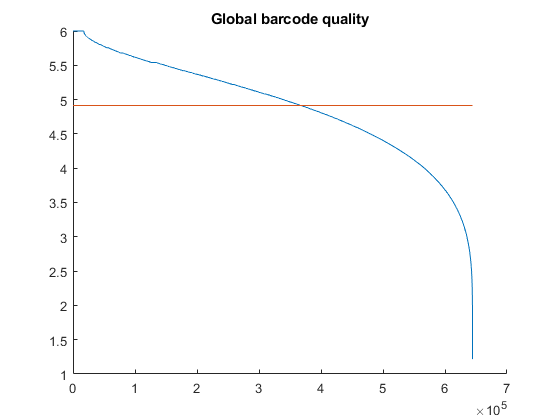

Iterate through clusters...[time = 2.69 s]


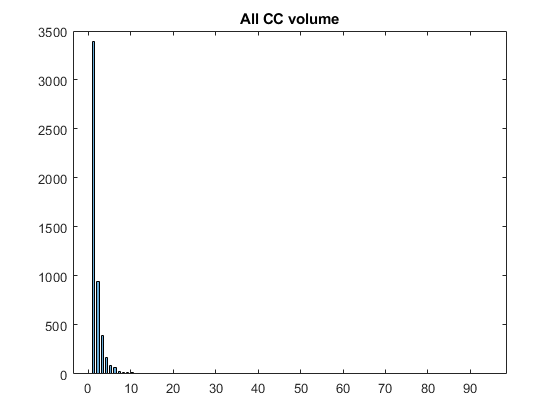

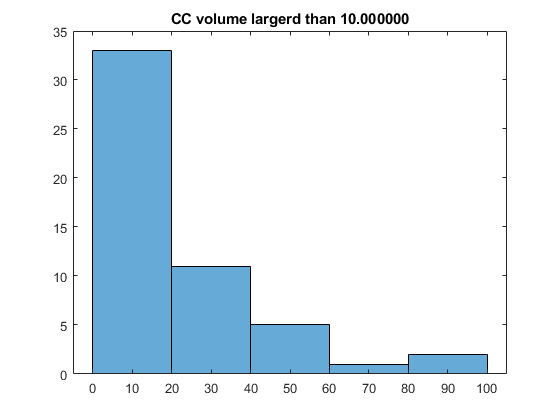

Number of spots found by barcode_test: 52
[time = 4.50 s]


new_run = new_run.SpotFinding('Method', "barcode_test", 'qualityThreshold', 0.01, ...
    'volumeThreshold', 10, 'barcodeMethod', "image", 'showPlots', true);


% new_run = new_run.ReadsExtraction('showPlots', false); 
new_run = new_run.ReadsFiltration('showPlots', false);

====Reads Filtration====
Base in both ends: C --- C
Filtration Statistics:
1.000000 [52 / 52] percent of good reads are CNNNNNC
1.000000 [52 / 52] percent of good reads are in codebook
1.000000 [52 / 52] percent of CNNNNNC reads are in codebook


gray_img = imread(fullfile(input_path, 'nissl/dapi_maxproj_resized.tif'));
gray_img = gray_img(2000:3024, 8000:9024);
bw_img = imbinarize(gray_img);

iter_centroids = new_run.goodSpots;
plot_centroids(iter_centroids, gray_img, bw_img, 'test')

image_centroids = new_run.goodSpots;
plot_centroids(iter_centroids, gray_img, bw_img, 'test')

run_id = '_log';
new_run = new_run.SpotFinding('Method', "log3d", 'qualityThreshold', 0.01, 'volumeThreshold', 1, 'showPlots', true);
new_run = new_run.ReadsExtraction('showPlots',false); 
new_run = new_run.ReadsFiltration('showPlots',false);
new_run = new_run.SaveReads('inputId', run_id);
new_run = new_run.AssignReads;
writetable(new_run.geneByCells, fullfile(new_run.outputPath, strcat('geneByCell', run_id,'.csv')));
new_run.jobFinished

new_run.Ncells
SaveSpotImages(new_run, strcat('spot', run_id, '.tif'));

% reset(curr_gpu)
% toc(starting)

SaveImages(new_run.registeredImages, new_run.outputPath, 'pub');
